clc;
close all;
clear;
addpath('C:\Users\pedem\Desktop\computer vision\Assignments\videos\'); 

## Change detection algorithm

- TAU1 tells us how much a pixel has to change with respect to the static beckground to be considered part of the foreground (values between 10/15 with low noise - to 30/40 for noisy videos). If it is too low we highlight noise, too high you miss some important info

- TAU2 used to define if a pixel is moving or not and consequently whether or not to update the background. If the pixel is moving you keep the old background. (values usually between 2/5 for slow movement - 10/20 for noisy scenes). Tau2 describe sensibility to movement, if it is too high you update also moving pixels, if it is too low you do not update the background and it remains fixed.

- APHA is the velocity of adaptation to changes, its value has to be between (0,1). If alpha=1 the background changes completely and becomes the new frame, instead with alpha=0 we keep the old background still

If we use: 

- (10, 0.7, 5) what we obtain for the static background is a binary map with a lot of white pixels, so probably we have to set a higher threshold in order to avoid nose's influence. For the moving average instead we adjust the background too fast (too big alpha) and the binary map contains only noise.

- (20, 0.02, 5) we obtain better results. For the static part we capture less noisy pixels and only changes due to light shadows. For the running average, the background is adjusted slowly but consistently and in the binary map we see only smaller changes, for instance the movement of the shadows in last frames. What happened in the first instants is no more visible in the ende, due to the change in background considered.

Background computed from 60 frames (60.00 seconds)


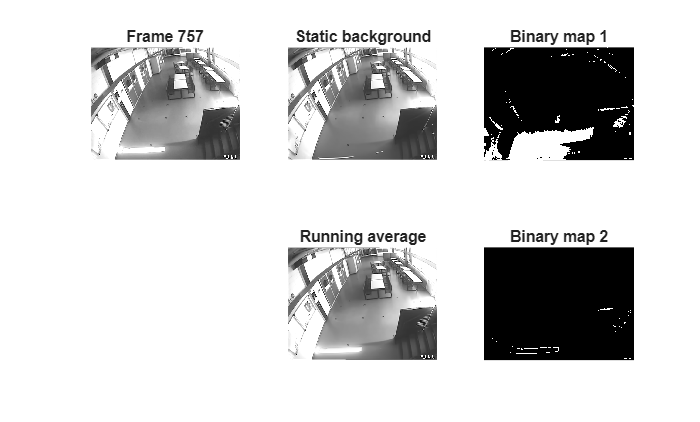

Finished displaying video: luce_vp_1part.mp4


video1="luce_vp_1part.mp4";
compareCDAlgo(video1,20,0.02,5)

## Change detection optical flow

second exercize

video2="tennis_2part.mp4";
compareCDOF(video2)

## Tracker

third exercize

video3="DibrisHall_3part.mp4";
segmentAndTrack(video3)